Combine 3D image segments into a single image

The zip file contains the original data split into 10x10 blocks of 200x200x~300. The file name gives the coordinates of each block for when you rebuild

source_dir = '~/placenta_patient_51';
placenta = [];
for j1=1:200:1801
%for j1=1:200:801 %half of the placenta for now
  rowSection = [];  
  for j2 = 1:200:1801
      filename = fullfile(source_dir,['P51_set_',num2str(j1),'_',num2str(j2),'.nii.gz']);
      segment = load_nii(filename);    
      rowSection = [rowSection,segment.img];
  end
  placenta=[placenta;rowSection];
end

placenta(placenta==1)=0 %remove non vessel placental tissue
volumeViewer(placenta); %visualise the vessels

write tiff slices from nii

0=background, 1=placenta(notvessel) as masked by Roz, 2=small vessel (as cleaned up by Claire last year) and 3=large vessel (mainly chorionic plate) estimated using an automatic vessel radius

convert the values to greyscale 0-255

tiff_dir = '~/placenta_patient_51/tiff';
slice = [];
for i=1:306 
  slice = placenta(:,:,i:i); 
  slice(slice > 0) = slice(slice > 0) * 85;
  filename = fullfile(tiff_dir,['P51_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

write tiff slices of vasculature from nii

0=background, 1=placenta(notvessel) as masked by Roz, 2=small vessel (as cleaned up by Claire last year) and 3=large vessel (mainly chorionic plate) estimated using an automatic vessel radius

convert the values to 0- background and 255 for vasculature

tiff_dir = '~/placenta_patient_51/tiff_vasculature';
slice = [];
for i=1:306 
  slice = placenta(:,:,i:i); 
  slice(slice == 1) = 0;
  slice(slice > 0) = 255;
  filename = fullfile(tiff_dir,['P51_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

write tiff slices of large vessels from nii

0=background, 1=placenta(notvessel) as masked by Roz, 2=small vessel (as cleaned up by Claire last year) and 3=large vessel (mainly chorionic plate) estimated using an automatic vessel radius

convert the values to 0- background and 255 for vasculature

tiff_dir = '~/placenta_patient_51/tiff_large_vessels';
slice = [];
for i=1:306 
  slice = placenta(:,:,i:i); 
  slice(slice == 1) = 0;
  slice(slice == 2) = 0;
  slice(slice > 0) = 255;
  filename = fullfile(tiff_dir,['P51_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

write tiff slices of small vessels from nii

0=background, 1=placenta(notvessel) as masked by Roz, 2=small vessel (as cleaned up by Claire last year) and 3=large vessel (mainly chorionic plate) estimated using an automatic vessel radius

convert the values to 0- background and 255 for vasculature

tiff_dir = '~/placenta_patient_51/tiff_small_vessels';
slice = [];
for i=1:306 
  slice = placenta(:,:,i:i); 
  slice(slice == 1) = 0;
  slice(slice == 3) = 0;
  slice(slice > 0) = 255;
  filename = fullfile(tiff_dir,['P51_slice_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

Write out a point cloud text file of the large vessel surface

source_dir = '~/placenta_patient_51/isosurfaces';
largeVessels2 = isosurface(placenta,2);
filename = fullfile(source_dir,'large_vessels.txt');
dlmwrite(filename,largeVessels2.vertices,'delimiter','\t');

Write out a point cloud text file of the small vessel surface

source_dir = '~/placenta_patient_51/isosurfaces';
placenta_copy = placenta
placenta_copy(placenta_copy==3)=0
smallVessels2 = isosurface(placenta_copy,1);
filename = fullfile(source_dir,'small_vessels.txt');
dlmwrite(filename,smallVessels2.vertices,'delimiter','\t');

Write out a point cloud text file of the placental surface

source_dir = '~/placenta_patient_51/isosurfaces';
placenta_copy = placenta
placenta_copy(placenta_copy==3)=0
placenta_copy(placenta_copy==2)=0
placenta_surface = isosurface(placenta_copy,0);
filename = fullfile(source_dir,'placental_surface.txt');
dlmwrite(filename,placenta_surface.vertices,'delimiter','\t');

source_dir = '~/placenta_patient_51/isosurfaces';
placenta_chunk = placenta(901:1100,901:1100,1:306);
largeVessels2 = isosurface(placenta_chunk,2);
filename = fullfile(source_dir,'large_vessel_chunk.txt');
dlmwrite(filename,largeVessels2.vertices,'delimiter','\t');

Skeletonize the 3D binary volume of the large blood vessels

large_vessels_3D = placenta
large_vessels_3D(large_vessels_3D==1) = 0;
large_vessels_3D(large_vessels_3D==2) = 0;
large_vessels_3D(large_vessels_3D>0) = 1;
binary_volume = logical(large_vessels_3D);
skel = Skeleton3D(binary_volume); 

Skeletonize the 3D binary volume of the small blood vessels

small_vessels_3D = placenta;
small_vessels_3D(small_vessels_3D==1) = 0;
small_vessels_3D(small_vessels_3D==3) = 0;
small_vessels_3D(small_vessels_3D>0) = 255;
binary_volume = logical(small_vessels_3D);
skel = Skeleton3D(binary_volume); 

Skeletonize the 3D binary volume of all vessels from high fidelity images

all_vessels_3D = vessels;
all_vessels_3D(all_vessels_3D>=105) = 1;
binary_volume = logical(all_vessels_3D);
skel = Skeleton3D(binary_volume); 

Out of memory. Type HELP MEMORY for your options.

Error in Skeleton3D (line 50)
                cands(:,y,:)=skel(:,y,:) - skel(:,y-1,:);

Write skeleton surface points to a text file

large vessels - lv_skeleton.txt

small vessels - sv_skeleton.txt

all vessels - all_vessels_skeleton.txt

skel_surface = isosurface(skel,0);
source_dir = '~/placenta_patient_51/isosurfaces';
filename = fullfile(source_dir,'sv_skeleton.txt');
dlmwrite(filename,skel_surface.vertices,'delimiter','\t');

skel_surface = isosurface(skel_chunk,0);
source_dir = '~/placenta_patient_51/isosurfaces';
filename = fullfile(source_dir,'skeleton_chunk.txt');
dlmwrite(filename,skel_surface.vertices,'delimiter','\t');

skel_surface = isosurface(skel,0);
source_dir = '~/p51_higher_fidelity_segmentation/isosurfaces';
filename = fullfile(source_dir,'all_vessels_skeleton.txt');
dlmwrite(filename,skel_surface.vertices,'delimiter','\t');

Plot the large vessel volume

clf;
inds = find(binary_volume);
[y,x,z] = ind2sub(size(binary_volume),inds);
s = scatter3(x,y,z,30,...
  'Marker','o',...
  'MarkerEdgeColor','none',...
  'MarkerFaceAlpha',0.3,...
  'MarkerFaceColor','c');
xlabel('x');
ylabel('y');
zlabel('z');
title('Large Vessel Volume')

Display points along the skeleton of the large vessels

inds = find(skel);
[yskel,xskel,zskel] = ind2sub(size(skel),inds);
hold on
p2 = scatter3(xskel,yskel,zskel,10,...
    'Marker','o',...
    'MarkerEdgeColor','none',...
    'MarkerFaceColor','r');

houskeeping functions and others

clearvars -except large_vessels_3D;
clear large_vessels_3D;
save('skeleton');
load('skeleton');
%to look at the source code of a function:
edit Skel2Graph3D

convert a 3D binary voxel skeleton into a network graph described by nodes and edges 

A is the adjacency matrix with the length of the links as matrix entries, and node/link are the structures describing node and link properties.

A node has the following properties:

    idx List of voxel indices of this node

    links List of links connected to this node

    conn List of destinations of links of this node

    comX,comY,comZ Center of mass of all voxels of this node

    ep 1 if node is endpoint (degree 1), 0 otherwise

A link has the following properties:

    n1 Node where link starts

    n2 Node where link ends

    point List of voxel indices of this link

THR is a threshold for the minimum length of branches, to filter out skeletonization artifacts (must be set to 0 when using the modified plugin version MB_Skel2Graph3D)

THR = 0; 
[A,node,link] = MB_Skel2Graph3D(skel,THR);

Index in position 1 is invalid. Array indices must be positive integers or logical values.

Error in pk_follow_link (line 15)
        cand = cans(next_cand,2);

Error in MB_Skel2Graph3D (line 203)
            [vox,n_idx,ept] = pk_follow_link(skel2,node,i,j,link_cands(k),cans,c2n);

Write skeleton graph to text files

write branch lengths

large vessels - element_length.csv

source_dir = '~/placenta_patient_51/matlab_skeleton_graph';
filename = fullfile(source_dir,'element_length_sv.csv');
A_full = full(A); %convert sparse matrix to a full one
dlmwrite(filename,A_full,'delimiter',',');

Write elements

large vessels - elements_mb.csv

source_dir = '~/placenta_patient_51/matlab_skeleton_graph';
filename = fullfile(source_dir,'elements_sv.csv');
cHeader = {'n1' 'n2' 'label'};
textHeader = strjoin(cHeader, ',');
%write header to file
fid = fopen(filename,'w'); 
fprintf(fid,'%s\n',textHeader);
fclose(fid);
%write data to end of file
elements = [link.n1;link.n2;link.label];
elements = elements';
dlmwrite(filename,elements,'delimiter',',','-append');

Write nodes

large vessels - nodes_mb.csv

source_dir = '~/placenta_patient_51/matlab_skeleton_graph';
filename = fullfile(source_dir,'nodes_sv.csv');
cHeader = {'comx' 'comy' 'comz' 'ep' 'label'};
textHeader = strjoin(cHeader, ',');
%write header to file
fid = fopen(filename,'w'); 
fprintf(fid,'%s\n',textHeader);
fclose(fid);
%write data to end of file
nodes = [node.comx;node.comy;node.comz;node.ep;node.label];
nodes = nodes';
dlmwrite(filename,nodes,'delimiter',',','-append');

get a skeleton chunk for testing

skel_chunk = skel(901:1100,901:1100,1:306);
THR = 0; 
[A,node,link] = MB_Skel2Graph3D(skel_chunk,THR);


Visualise the large vessel skeleton

clf;
patch(skel_surface,'FaceColor','g','EdgeColor','none')
view(30,-15)
camlight(-10,10)
axis equal
title('Large Vessel Skeleton')

Write tiff slices of of the large vessel skeleton

tiff_dir = '~/placenta_patient_51/tiff_matlab_skeleton';
skel_int = int8(skel);
slice = [];
for i=1:306 
  slice = skel_int(:,:,i:i); 
  slice(slice > 0) = 255;
  filename = fullfile(tiff_dir,['P51_mat_skeleton_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

volumeViewer(skel_int);

Visualise the placental surface and fetal blood vessels

clf;
placentaSurface = isosurface(placenta,0);
patch(placentaSurface,'FaceColor','g','EdgeColor','none')
placenta_copy = placenta
placenta_copy(placenta_copy==3)=0
smallVessels = isosurface(placenta_copy,1);
patch(smallVessels,'FaceColor','b','EdgeColor','none')
largeVessels = isosurface(placenta,2);
patch(largeVessels,'FaceColor','r','EdgeColor','none')
view(30,-15)     % Setting view
camlight(-10,10)   % Adjusting camera light
axis equal 
title('Placenta and Fetal Vessel Surfaces')

Generate seed points for growing blood vessels filling the volume of the placenta

Populate the volume of the placenta with vessel seed points


placenta_volume = zeros(2000,2000,306);
slice = [];
for i=1:306
  slice = placenta(:,:,i:i); 
  slice(slice > 1) = 1; %remove small and large vessels
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_volume(:,:,i)=slice;
end

points every 10 voxels in each direction

placenta_points = zeros(2000,2000,306);

for i=1:10:306
  slice = placenta_volume(:,:,i:i); 
  for j=1:10:2000
      for n=1:10:2000
          if(slice(j,n)==1)
              slice(j,n) = 2;
          end
      end
  end
  slice(slice==1) = 0;
  slice(slice==2) = 1;
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_points(:,:,i)=slice;
end

Write tiff slices of placenta points - point every 5, 10 or 15 units in each direction

tiff_dir = '~/placenta_patient_51/seed_points_every_20_units';
%tiff_dir = '~/placenta_patient_51/seed_points_every_15_units';
%tiff_dir = '~/placenta_patient_51/seed_points_every_10_units';
%tiff_dir = '~/placenta_patient_51/seed_points_every_5_units';
slice = [];
for i=1:306 
  slice = placenta_points(:,:,i:i); 
  filename = fullfile(tiff_dir,['P51_seed_points_',num2str(i),'.tiff']);
  imwrite(uint8(slice),filename);
end

placenta seed points every 5 units in each direction

placenta_points = zeros(2000,2000,306);

for i=1:5:306
  slice = placenta_volume(:,:,i:i); 
  for j=1:5:2000
      for n=1:5:2000
          if(slice(j,n)==1)
              slice(j,n) = 2;
          end
      end
  end
  slice(slice==1) = 0;
  slice(slice==2) = 1;
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_points(:,:,i)=slice;
end

placenta seed points every 15 units in each direction

placenta_points = zeros(2000,2000,306);

for i=1:15:306
  slice = placenta_volume(:,:,i:i); 
  for j=1:15:2000
      for n=1:15:2000
          if(slice(j,n)==1)
              slice(j,n) = 2;
          end
      end
  end
  slice(slice==1) = 0;
  slice(slice==2) = 1;
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_points(:,:,i)=slice;
end

placenta seed points every 20 units in each direction

placenta_points = zeros(2000,2000,306);

for i=1:20:306
  slice = placenta_volume(:,:,i:i); 
  for j=1:20:2000
      for n=1:20:2000
          if(slice(j,n)==1)
              slice(j,n) = 2;
          end
      end
  end
  slice(slice==1) = 0;
  slice(slice==2) = 1;
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  placenta_points(:,:,i)=slice;
end

Visualise the placental volume

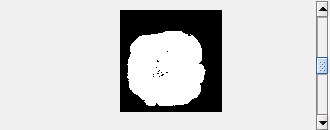

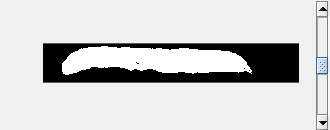

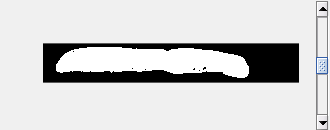

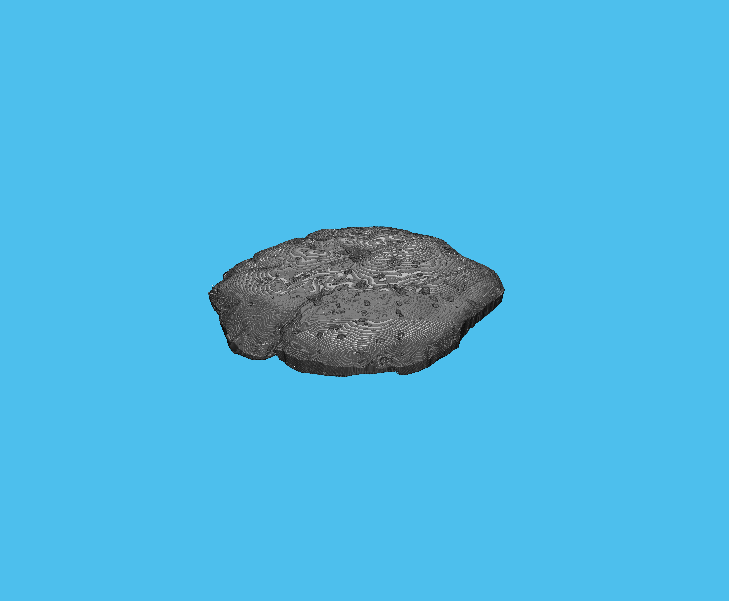

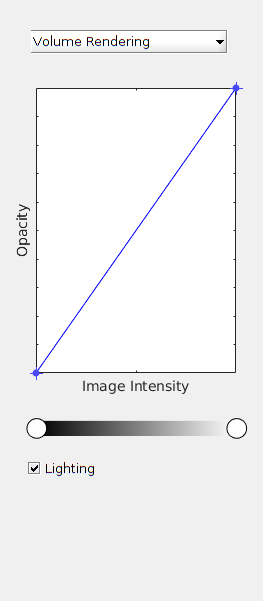

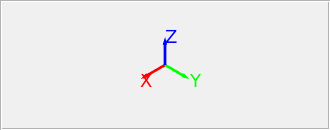

volumeViewer(placenta_volume);

Plot placenta points

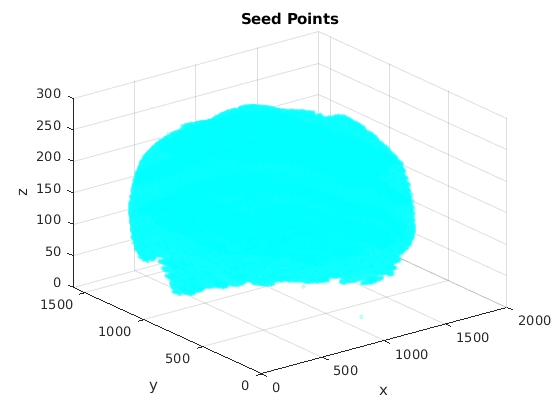

clf;
inds = find(placenta_points);
[y,x,z] = ind2sub(size(placenta_points),inds);
s = scatter3(x,y,z,10,...
  'Marker','o',...
  'MarkerEdgeColor','none',...
  'MarkerFaceAlpha',0.3,...
  'MarkerFaceColor','c');
xlabel('x');
ylabel('y');
zlabel('z');
title('Seed Points')

Populate array with small vessel values only

small_vessels = zeros(2000,2000,306);
slice = [];
for i=1:306
  slice = placenta(:,:,i:i); 
  slice(slice > 2) = 0; % remove large vessels
  slice(slice == 1) = 0; % remove placenta
  %[row,col] = find(slice) %row and column subscripts of non-zero elements
  small_vessels(:,:,i)=slice;
end

Plot small vessel points

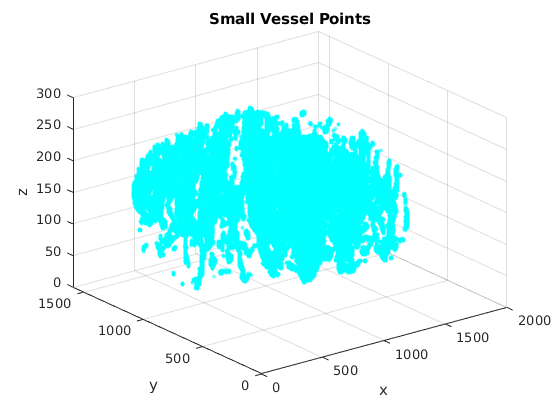

clf;
inds_sv = find(small_vessels);
[y_sv,x_sv,z_sv] = ind2sub(size(small_vessels),inds_sv);
s = scatter3(x_sv,y_sv,z_sv,10,...
  'Marker','o',...
  'MarkerEdgeColor','none',...
  'MarkerFaceAlpha',0.3,...
  'MarkerFaceColor','c');
xlabel('x');
ylabel('y');
zlabel('z');
title('Small Vessel Points')

inds = find(placenta_points);
[y,x,z] = ind2sub(size(placenta_points),inds);
for i=1:length(y)
    x_sub = x(i);
    y_sub = y(i);
    z_sub = z(i);
    %get 11 by 11 by 11 voxel cube surrounding the seed from the small vessel array
    % -5
    %get 21 by 21 by 21 voxel cube
    %-10
    %get 15 by 15 by 15 voxel cube
    x_sub_start = x_sub-7;
    if x_sub_start<1
        x_sub_start = 1;
    end
    x_sub_end = x_sub + 7;
    if x_sub_end > 2000
        x_sub_end = 2000;
    end
    y_sub_start = y_sub - 7;
    if y_sub_start<1
        y_sub_start = 1;
    end
    y_sub_end = y_sub + 7;
    if y_sub_end > 2000
        y_sub_end = 2000;
    end
    z_sub_start = z_sub - 7;
    if z_sub_start<1
        z_sub_start = 1;
    end
    z_sub_end = z_sub + 7;
    if z_sub_end > 306
        z_sub_end = 306;
    end        
    %small_vessels(y,x,z)
    cube = small_vessels(y_sub_start:y_sub_end,x_sub_start:x_sub_end,z_sub_start:z_sub_end);
    surrounding_small_vessels = find(cube);
    if isempty(surrounding_small_vessels)
        %remove the seed placed in an area where no small vessels exist
        placenta_points(y_sub,x_sub,z_sub) = 0;
    end
end


write the seed point coordinates to a text file 

placenta_seed_points.txt keeps all points

placenta_seed_points_v2.txt has no seed points within 11 by 11 by 11 cubes that don't contain small vessel voxels

placenta_seed_points_v3.txt has no seed points within 21 by 21 by 21 cubes that don't contain small vessel voxels

placenta_seed_points_v4.txt has no seed points within 15 by 15 by 15 cubes that don't contain small vessel voxels

placenta_seed_points_v5.txt variable density of seed points every 5, 10 or 15 units depending on vascular density > 0

placenta_seed_points_v6.txt variable density of seed points every 10, 15 or 20 units depending on vascular density > 0, cube 20X20X20 (around 26,000 points)

placenta_seed_points_v7.txt variable density of seed points every 10, 15 or 20 units depending on vascular density > 0, cube 25X25X25 (29,185 points)

inds = find(placenta_points);
[y,x,z] = ind2sub(size(placenta_points),inds);
source_dir = '~/placenta_patient_51/volume';
filename = fullfile(source_dir,'placenta_seed_points_v7.txt');
dlmwrite(filename,[x,y,z],'delimiter','\t');


load csv file with small vessel radii based on pre-segmented images

source_dir = '~/placenta_patient_51/';
filename = fullfile(source_dir,'small vessel radii presegmented images.csv');
sv_radii = csvread(filename);
histogram(sv_radii);